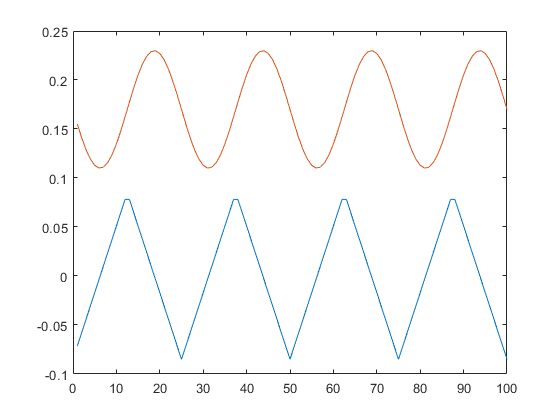


close all;clear;clc; 
p=0;
n = 100;
x = ones(1,n);
y = ones(1,n);
theta2 = ones(1,n);
gamma2 = ones(1,n);
angle1 = ones(1,n);
angle2 = ones(1,n);
j = 1:1:n;
for i=1:n
    stance_height = 0.17;
    down_amp = 0.06;
    up_amp = 0.06;
    flight_percent = 0.5;
    step_length = 0.17;
    figure(1);
    diff_t = 0.02;
    FREQ = 2;
    p = p+FREQ*diff_t;
    
    gp = mod(p,1.0);
    if(gp<flight_percent)
        x(i) = (gp/flight_percent)*step_length - step_length/2.0;
        y(i) = -up_amp*sin(pi*gp/flight_percent) + stance_height;
        [theta1, gamma1] = getgamma(x(i),y(i));
        theta2(i) = theta1;
        gamma2(i) = gamma1;
        angle1(i) = theta1+gamma1; 
        angle2(i) = -gamma1+theta1;
        %plot(i,gamma1,"*");
        %plot(i,theta1,"*");
        %plot(i,x,".");
        %plot(i,y,".");
    end
    if(gp>flight_percent)
        percentBack = (gp-flight_percent)/(1.0-flight_percent);
        x(i) = -percentBack*step_length + step_length/2.0;
        y(i) = down_amp*sin(pi*percentBack) + step_length;
        [theta1, gamma1] = getgamma(x(i),y(i));
        theta2(i) = theta1;
        gamma2(i) = gamma1;
        angle1(i) = theta1+gamma1; 
        angle2(i) = -gamma1+theta1;
        %plot(i,gamma1,"*");
        %plot(i,theta1,"*");
        %plot(i,x,".");
        %plot(i,y,".");
    end
    %plot(i,-gamma1+theta1,".");
    %plot(i,gamma1+theta1,".");
end
figure(1);
plot(j,x,j,y);

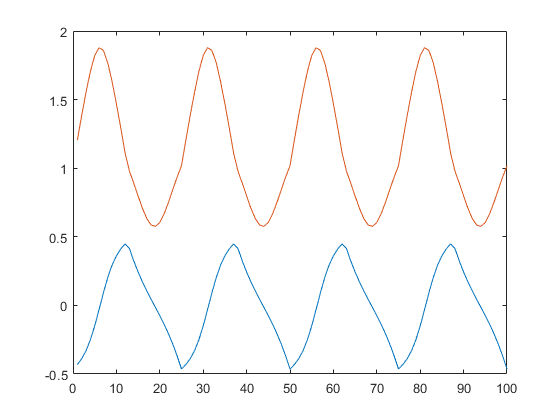

figure(2);
plot(j,theta2,j,gamma2);

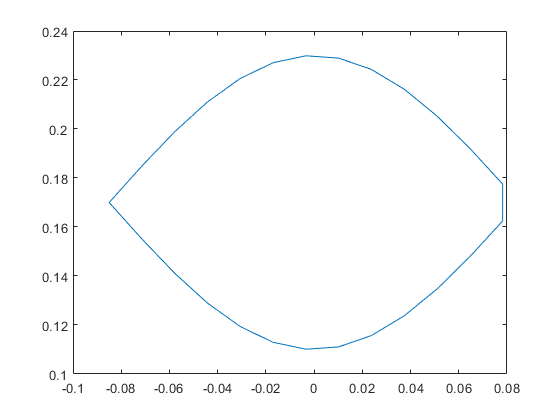

figure(3);
plot(x,y);

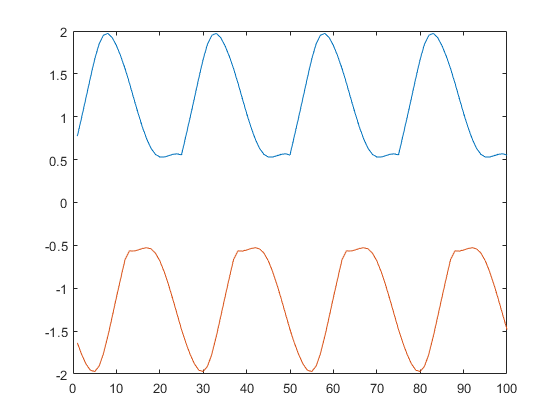

figure(4);
plot(j,angle1,j,angle2);

%plot(j,y);